# using SINDy to discover the Lotka-Volterra equations

clear all
close all
clc
figpath = '../figures/';        % not sure 
addpath('./utils');             % the folder w/ the functions 


## generate data

% what candidate terms in the library 
polyorder = 3;
usesine = 0;

% the coefficients in the (rearranged) lotka-volterra equations 
a = 0.05;
b = 0.0005;
c = 0.0005;
d = 0.2;

n = 2;                          % number of equations

x0=[1500; 100];                     % initial conditions

% Integrate
tspan=[.001:.001:200];          % change time to suit data
N = length(tspan);
options = odeset('RelTol',1e-12,'AbsTol',1e-12*ones(1,n));          % odeset creates an ode
[t,x]=ode45(@(t,x) lotkavol(t,x,a,b,c,d),tspan,x0,options);         % ode45 solves ODEs, 
                                                                    % lotkavol applies the system of equations

## compute derivative

eps = 1;
for i=1:length(x)
    dx(i,:) = lotkavol(0,x(i,:),a,b,c,d);        % changed to lotkavol fn
end
dx = dx + eps*randn(size(dx));


## build library of nonlinear time series

Theta = poolData(x,n,polyorder,usesine);            % kept the same 
m = size(Theta,2);

## compute sparse regression: sequential least squares

lambda = 0.0002;      % lambda is our sparsification term 
Xi = sparsifyDynamics(Theta,dx,lambda,n)

Xi =    -0.0003    0.0022
    0.0500         0
         0   -0.2000
         0         0
   -0.0005    0.0005
         0         0
         0         0
         0         0
         0         0
         0         0


poolDataLIST({'u','v'},Xi,n,polyorder,usesine);         %poolDataLIST sets it up and outputs 'newout'

newout = 11×3 cell array
    {0×0 char}    {'udot'       }    {'vdot'      }
    {'1'     }    {[-2.9052e-04]}    {[    0.0022]}
    {'u'     }    {[     0.0500]}    {[         0]}
    {'v'     }    {[          0]}    {[   -0.2000]}
    {'uu'    }    {[          0]}    {[         0]}
    {'uv'    }    {[-5.0001e-04]}    {[5.0003e-04]}
    {'vv'    }    {[          0]}    {[         0]}
    {'uuu'   }    {[          0]}    {[         0]}
    {'uuv'   }    {[          0]}    {[         0]}
    {'uvv'   }    {[          0]}    {[         0]}
    {'vvv'   }    {[          0]}    {[         0]}


## plot dynamo view

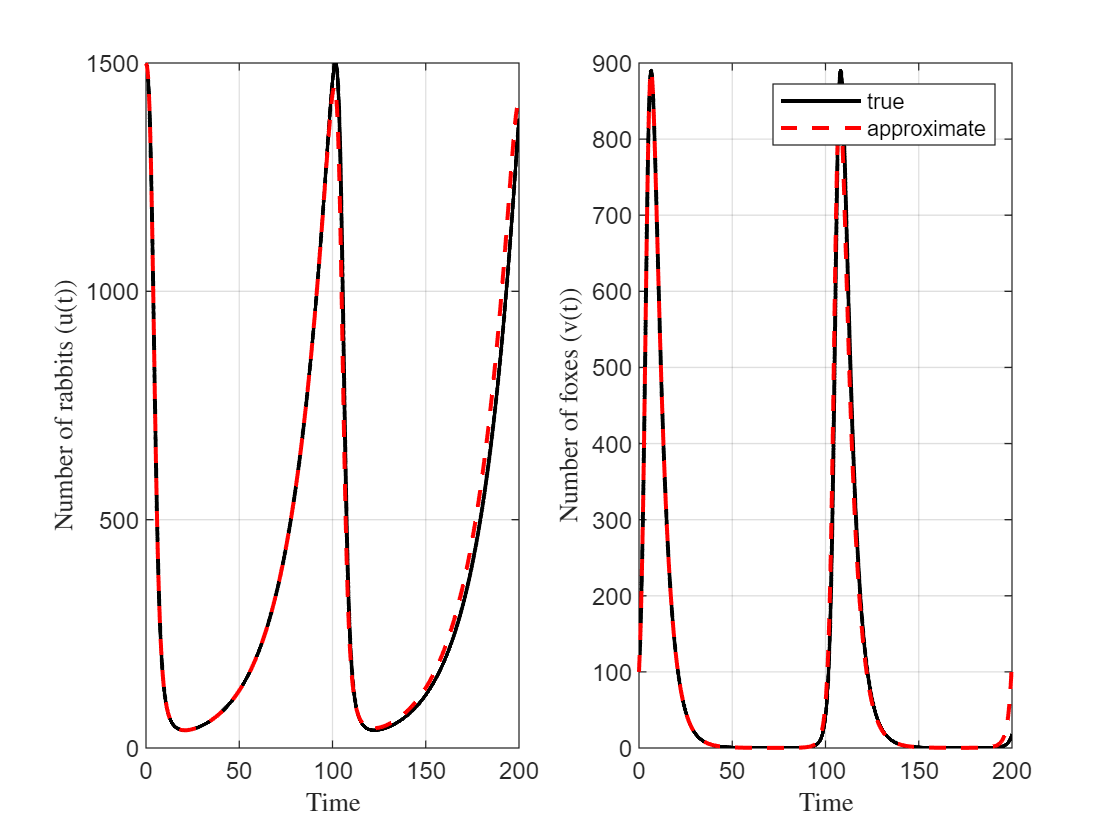

tspan = [0 200];
[tA,xA]=ode45(@(t,x)lotkavol(t,x,a,b,c,d),tspan,x0,options);   % true model
[tB,xB]=ode45(@(t,x)sparseGalerkin(t,x,Xi,polyorder,usesine),tspan,x0,options);  % approximate

figure
subplot(1,2,1)
title('Number of rabbits (u(t))')
plot(tA,xA(:,1),'k','LineWidth',1.5), hold on
plot(tB,xB(:,1),'r--','LineWidth',1.5)
grid on
xlabel('Time')
ylabel('Number of rabbits (u(t))')
%set(gca,'FontSize',13)
subplot(1,2,2)
plot(tA,xA(:,2),'k','LineWidth',1.5), hold on
plot(tB,xB(:,2),'r--','LineWidth',1.5)
grid on
xlabel('Time')
ylabel('Number of foxes (v(t))')
legend('true','approximate')

## plot phase plane view

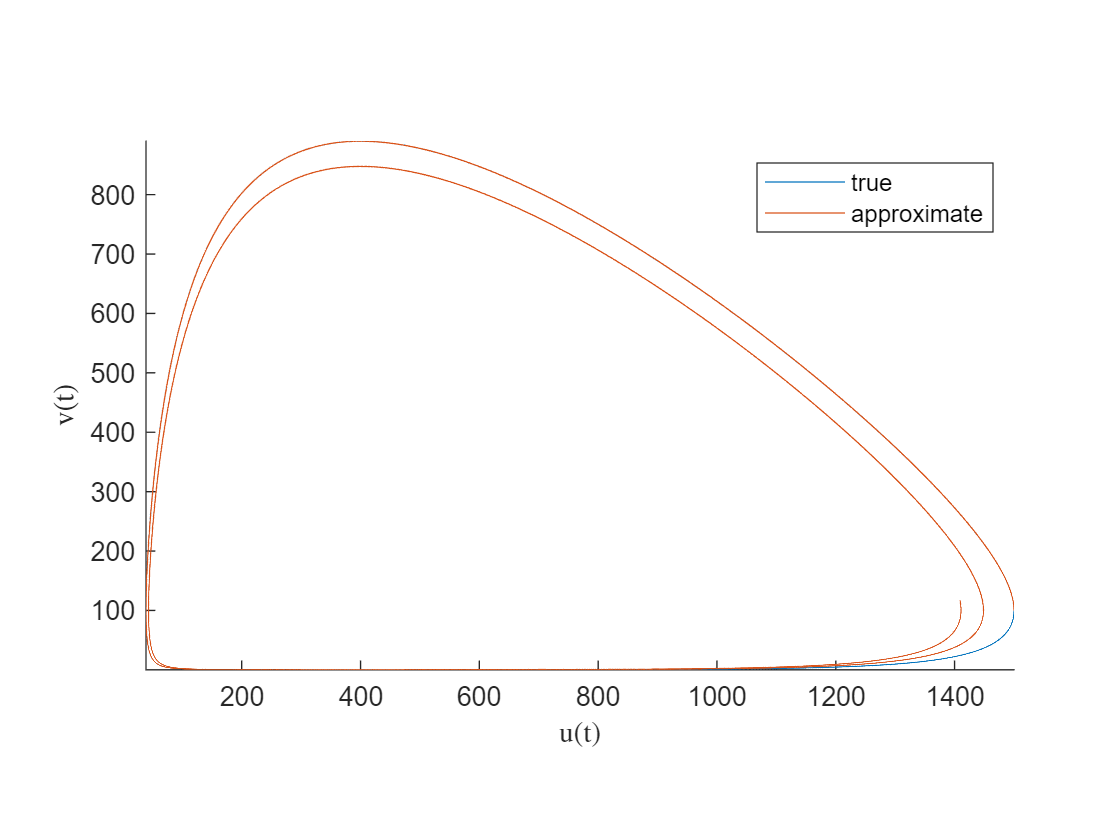

% % plot vector field
% [u, v] = meshgrid(-.5:0.05:0.5, -.5:.05:.5);
% udot = a*u-b*u.*v;
% vdot = c*u.*v-d*v;
figure
hold on
% quiver(u, v, udot, vdot)

% plot solution 
plot(xA(:,1),xA(:,2))           %plot true soln
plot(xB(:,1),xB(:,2))           %plot approx soln
xlabel('u(t)')
ylabel('v(t)')
axis tight equal;
hold off

legend('true','approximate')